En este script se entrena y se prueba un agente de aprendizaje por refuerzo con el algoritmo Deep Deterministic Policy Gradient (DDPG).

Nota: en esta versión se utiliza la arquitectura de red del artículo original (Continuous control with deep reinforcement learning).

Primera parte: crear el ambiente:

load("variables.mat"); % se cargan las variables
modelo = "rl_3tank";
open_system(modelo);

Acción

actInfo = rlNumericSpec([2 1]); % recibe la dimensión de la acción [Q1 Q2]
actInfo.Name = "flujo";

Observación

la observación es un arreglo de 5x1 (h1, e1, h2, e2, h3)

obsInfo = rlNumericSpec([5 1], ...
    LowerLimit=transpose([0 -inf 0 -inf 0]), ...
    UpperLimit=transpose([inf inf inf inf inf]));
obsInfo.Name = "observaciones";
obsInfo.Description = "altura 1, error 1, altura 2, error 2, altura 3";

Ambiente

env = rlSimulinkEnv(modelo, modelo + "/RL Agent", obsInfo, actInfo);
env.ResetFcn = @(in)localResetFcn(in);

Periodo de muestreo y tiempo total de simulación.

Ts = 1.0; % sample time
Tf = 300; % tiempo de finalización

Semilla para números aleatorios.

semilla = 750; % para reproducir resultados
rng(semilla);

Segunda parte: crear al crítico (red neuronal para función Q)

Entrada 1: observación

obsPath = [
    featureInputLayer(obsInfo.Dimension(1), Name="obsInLyr")
    fullyConnectedLayer(400)
    reluLayer
    fullyConnectedLayer(300, Name="obsPathOutLyr")];

Entrada 2: acción

actPath = [
    featureInputLayer(actInfo.Dimension(1), Name="actInLyr")
    fullyConnectedLayer(300, Name="actPathOutLyr")];

Trayectoria común

commonPath = [
    additionLayer(2, Name="add")
    reluLayer
    fullyConnectedLayer(1, Name="Qvalue")];


Red del crítico

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork, obsPath);
criticNetwork = addLayers(criticNetwork, actPath);
criticNetwork = addLayers(criticNetwork, commonPath);
criticNetwork = connectLayers(criticNetwork, "obsPathOutLyr", "add/in1");
criticNetwork = connectLayers(criticNetwork, "actPathOutLyr", "add/in2");

Se observa la arquitectura de la red

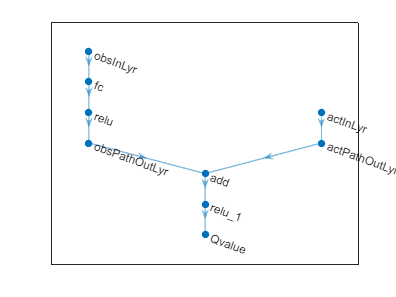

figure
plot(criticNetwork);

Crear una red neuronal de tipo dlnetwork.

criticNetwork = dlnetwork(criticNetwork);
summary(criticNetwork);

   Initialized: true

   Number of learnables: 123.9k

   Inputs:
      1   'obsInLyr'   5 features
      2   'actInLyr'   2 features



Función de aproximación para el crítico

critic = rlQValueFunction(criticNetwork, obsInfo,actInfo, ObservationInputNames="obsInLyr", ActionInputNames="actInLyr");

Se puede observar un forward del crítico

getValue(critic, {rand(obsInfo.Dimension)}, {rand(actInfo.Dimension)})

ans = single
0.0578

Tercera parte: crear al actor (red neuronal asociada a la política)

actorNetwork = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(400)
    reluLayer
    fullyConnectedLayer(300)
    reluLayer
    fullyConnectedLayer(actInfo.Dimension(1))
    sigmoidLayer]; % la capa sigmoide es para acotar entre 0 y 1

Crear objeto dlnetwork

actorNetwork = dlnetwork(actorNetwork);
summary(actorNetwork)

   Initialized: true

   Number of learnables: 123.3k

   Inputs:
      1   'input'   5 features



Crear función de aproximación

actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

Se puede observar un forward del actor

getAction(actor, {rand(obsInfo.Dimension)});

Cuarta parte: crear el agente DDPG

agent = rlDDPGAgent(actor, critic);

Parámetros obtenidos del paper: continuous control with deep reinforcement learning

agent.SampleTime = Ts;

agent.AgentOptions.TargetSmoothFactor = 1e-3;
agent.AgentOptions.DiscountFactor = 0.99;
agent.AgentOptions.MiniBatchSize = 64;
agent.AgentOptions.ExperienceBufferLength = 1e5; % modificado 10^6 -> 10^5

agent.AgentOptions.NoiseOptions.Variance = 0.2; % cambié de 0.3 -> 0.2
agent.AgentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-03;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-04;
agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;

Se puede verificar una acción

getAction(agent, {rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {2×1 double}


Quinta parte: fase de entrenamiento

trainOpts = rlTrainingOptions(...
    MaxEpisodes = 1000, ...
    MaxStepsPerEpisode = ceil(Tf/Ts), ...
    ScoreAveragingWindowLength = 20, ...
    Verbose=false, ...
    Plots = "training-progress",...
    StopTrainingCriteria = "AverageReward",...
    StopTrainingValue = 300000); % modificado en la v4

Se guardará el estado del agente cuando haya terminado el entrenamiento

% cambiar variable dependiendo si se quiere entrenar o no.
doTraining = false;

if doTraining
    trainingStats = train(agent, env, trainOpts);
    save("agenteDDPG.mat", "agent");
else
    load("agenteDDPG.mat", "agent");
end

Sexta parte: fase de control

rng(semilla);
simOpts = rlSimulationOptions(MaxSteps=ceil(Tf/Ts), StopOnError="on");
experiences = sim(env,agent,simOpts);

Función para reinicio aleatorio

function in = localResetFcn(in)
    H_max = 0.62;

    % Randomize reference signal
    % valor de referencia 1
    blk1 = "rl_3tank/goal1";
    h1 = rand*H_max; % distribución uniforme
    in = setBlockParameter(in, blk1, Value=num2str(h1));

    % valor de referencia 2
    blk2 = "rl_3tank/goal2";
    h2 = rand*h1;
    in = setBlockParameter(in, blk2, Value=num2str(h2));

    % Randomize initial height
    % Altura inicial: tanque 1
    h = randn + H_max/2;
    while h <= 0 || h >= H_max
        h = randn + H_max/2;
    end
    bloque_h1 = "rl_3tank/Tres_tanques/Tanque_1/altura";
    in = setBlockParameter(in, bloque_h1, InitialCondition=num2str(h));

    % Altura inicial: tanque 2
    h = randn + H_max/2;
    while h <= 0 || h >= H_max
        h = randn + H_max/2;
    end
    bloque_h2 = "rl_3tank/Tres_tanques/Tanque_2/altura";
    in = setBlockParameter(in, bloque_h2, InitialCondition=num2str(h));

    % Altura inicial: tanque 3
    h = randn + H_max/2;
    while h <= 0 || h >= H_max
        h = randn + H_max/2;
    end
    bloque_h3 = "rl_3tank/Tres_tanques/Tanque_3/altura";
    in = setBlockParameter(in, bloque_h3, InitialCondition=num2str(h));
end